clear;
file = 'potdng';

%ims = zeros(4, 2000-16, 1500-16, 3, 'single');
ims = zeros(4, 2000-24, 1500-24, 3, 'single');

for x=0:3
    deg = num2str(45 * x);
    ims(x+1, :, :, :) = imread(strcat('cut/', file, deg, '.tif'));
end
clear deg;

ims = gpuArray(rgb2lin(ims / 255.0));


% Noise reduce.
for i = 1:8
    for x = 1:4
        %ims(x, :, :, :) = bilateral(squeeze(ims(x, :, :, :)), 1.0, 0.01);
    end
end
clear x;

imsfft = fft(ims, 4, 1) * 0.5;
clear ims;

MeanRGB = squeeze(abs(imsfft(1, :, :, :))) * 0.5; % 0.5 * Diffuse + 0.5 * Perp + 0.5 * Parallel
CosRGB = squeeze(abs(imsfft(2, :, :, :))); % 0.5 * (Perp - Parallel)

clear imsfft;
clear i;

imshow(lin2rgb(gather(MeanRGB)));
imshow(lin2rgb(gather(CosRGB)));

imwrite(uint8(255.0 .* lin2rgb(gather(MeanRGB))), strcat('iter/', file, 'mean', int2str(0), '.tif'));

% Select channel with lowest coefficient for projection on boundary.
CosFactor_Max = min(max(0.0001, MeanRGB) ./ max(0.0001, CosRGB), [], 3);
CosFactor_Min = gpuArray(ones(size(CosFactor_Max)));

imwrite(uint8(255.0 .* lin2rgb(gather(MeanRGB - (CosFactor_Min .* CosRGB)))), strcat('iter/', file, 'min', 'dif', int2str(0), '.tif'));
imwrite(uint8(255.0 .* lin2rgb(gather(CosFactor_Min .* CosRGB))), strcat('iter/', file, 'min', 'spec', int2str(0), '.tif'));
imwrite(uint8(128.0 .* sqrt(abs(CosFactor_Min - 1.0))), strcat('iter/', file, 'min', 'ratio', int2str(0), '.tif'));

imwrite(uint8(255.0 .* lin2rgb(gather(MeanRGB - (CosFactor_Max .* CosRGB)))), strcat('iter/', file, 'max', 'dif', int2str(0), '.tif'));
imwrite(uint8(255.0 .* lin2rgb(gather(CosFactor_Max .* CosRGB))), strcat('iter/', file, 'max', 'spec', int2str(0), '.tif'));
imwrite(uint8(128.0 .* sqrt(abs(CosFactor_Max - 1.0))), strcat('iter/', file, 'max', 'ratio', int2str(0), '.tif'));

% imshow(lin2rgb(gather(MeanRGB - (CosFactor_Min .* CosRGB))));
% imshow(lin2rgb(gather(MeanRGB - (CosFactor_Max .* CosRGB))));

[qytotal, qxtotal] = size(CosFactor_Max);
divcount = 4;
qypart = qytotal / divcount;
qxpart = qxtotal / divcount;

sigma_spatial_1 = 2.33;
sigma_spatial_2 = 0.75;
sigma_tonal = 0.04;

IterCount = 11;
for i = 1:IterCount
    tic;
    % Do the bilateral update based on Fresnel ratios at once.
    CosFactor_Min = bilateralx(CosFactor_Min, MeanRGB, sigma_spatial_1, sigma_tonal);
    CosFactor_Max = bilateralx(CosFactor_Max, MeanRGB, sigma_spatial_1, sigma_tonal);
    %toc;
    
    %tic;
    % Divide line-intersection in 16 sub-parts for memory usage.
    CosFactor_Min_Copy = CosFactor_Min;
    CosFactor_Max_Copy = CosFactor_Max;
    
    for qy = 0:(divcount-1)
        yoffset = qypart * qy;
        ycoords = (yoffset+1):(yoffset+qypart);
        for qx = 0:(divcount-1)
            xoffset = qxpart * qx;
            xcoords = (xoffset+1):(xoffset+qxpart);
            
            CFMinChunk = CosFactor_Min(ycoords, xcoords);
            CFMaxChunk = CosFactor_Max(ycoords, xcoords);
            
            % CosFactor_Min_Copy(ycoords, xcoords) = bilaterallinex(ycoords, xcoords, MeanRGB, CosRGB, CosFactor_Min, sigma_spatial_2, sigma_tonal, @(x) x);
            % CosFactor_Max_Copy(ycoords, xcoords) = bilaterallinex(ycoords, xcoords, MeanRGB, CosRGB, CosFactor_Max, sigma_spatial_2, sigma_tonal, @(x) x);

            CosFactor_Min_Copy(ycoords, xcoords) = bilaterallinex(ycoords, xcoords, MeanRGB, CosRGB, CosFactor_Min, sigma_spatial_2, sigma_tonal, @(x) min(max(x, CFMinChunk), CFMaxChunk));
            CosFactor_Max_Copy(ycoords, xcoords) = bilaterallinex(ycoords, xcoords, MeanRGB, CosRGB, CosFactor_Max, sigma_spatial_2, sigma_tonal, @(x) max(min(x, CFMaxChunk), CFMinChunk));
        end
    end
    
    CosFactor_Min = CosFactor_Min_Copy;
    CosFactor_Max = CosFactor_Max_Copy;
    toc;
    
    % CosFactor_Min_min = gather(min(CosFactor_Min, [], [1 2]));
    % CosFactor_Min_max = gather(max(CosFactor_Max, [], [1 2]));
    % CosFactor_Min_nan = gather(sum(isnan(CosFactor_Min), [1 2]));
    
    if mod(i, 2) == 1
        imwrite(uint8(255.0 .* lin2rgb(gather(MeanRGB - (CosFactor_Min .* CosRGB)))), strcat('iter/', file, 'min', 'dif', int2str(i), '.tif'));
        imwrite(uint8(255.0 .* lin2rgb(gather(CosFactor_Min .* CosRGB))), strcat('iter/', file, 'min', 'spec', int2str(i), '.tif'));
        imwrite(uint8(128.0 .* sqrt(abs(CosFactor_Min - 1.0))), strcat('iter/', file, 'min', 'ratio', int2str(i), '.tif'));

        imwrite(uint8(255.0 .* lin2rgb(gather(MeanRGB - (CosFactor_Max .* CosRGB)))), strcat('iter/', file, 'max', 'dif', int2str(i), '.tif'));
        imwrite(uint8(255.0 .* lin2rgb(gather(CosFactor_Max .* CosRGB))), strcat('iter/', file, 'max', 'spec', int2str(i), '.tif'));
        imwrite(uint8(128.0 .* sqrt(abs(CosFactor_Max - 1.0))), strcat('iter/', file, 'max', 'ratio', int2str(i), '.tif'));
    end
end

Elapsed time is 6.324049 seconds.
Elapsed time is 5.929283 seconds.
Elapsed time is 5.680495 seconds.
Elapsed time is 5.517451 seconds.
Elapsed time is 5.369464 seconds.
Elapsed time is 5.431831 seconds.
Elapsed time is 5.684670 seconds.
Elapsed time is 5.581755 seconds.
Elapsed time is 5.433787 seconds.
Elapsed time is 5.366004 seconds.
Elapsed time is 5.433789 seconds.



clear divcount;
clear i;
clear IterCount;
clear qx;
clear qxpart;
clear qxtotal;
clear qy;
clear qypart;
clear qytotal;
clear xcoords;
clear xoffset;
clear ycoords;
clear yoffset;
clear sigma_spatial_1;
clear sigma_spatial_2;
clear sigma_tonal;
clear CFMinChunk;
clear CFMaxChunk;
clear CosFactor_Min_min;
clear CosFactor_Min_max;
clear CosFactor_Min_nan;
clear CosFactor_Min_Copy;
clear CosFactor_Max_Copy;

CosFactor = CosFactor_Max;

imshow(lin2rgb(gather(MeanRGB - (CosFactor_Min .* CosRGB))));
imshow(lin2rgb(gather(MeanRGB - (CosFactor_Max .* CosRGB))));

imshow(lin2rgb(gather(CosFactor_Min .* CosRGB)));
imshow(lin2rgb(gather(CosFactor_Max .* CosRGB)));
imshow(lin2rgb(gather(CosRGB)));

imshow(lin2rgb(gather(MeanRGB - (CosFactor .* CosRGB))));
imshow(lin2rgb(gather(CosFactor .* CosRGB)));

Specular = CosFactor .* CosRGB;
Diffuse = max(0.0, MeanRGB - Specular);

for i = 1:3
    Diffuse(:, :, i) = medfilt2(Diffuse(:, :, i));
end

Specular = max(0.0, MeanRGB - Diffuse);
clear i;

imshow(lin2rgb(gather(Diffuse)));
imshow(lin2rgb(gather(Specular)));

% Testing.
MinVal = MeanRGB - CosFactor_Min .* CosRGB;
AlbedoMinLightMap = euclidianlength(MinVal, 3);
AlbedoMin = MinVal ./ AlbedoMinLightMap;
imshow(lin2rgb(gather(MinVal)));
imshow(lin2rgb(gather(AlbedoMin)));
imshow(lin2rgb(gather(AlbedoMinLightMap)));

MaxVal = MeanRGB - CosFactor_Max .* CosRGB;
AlbedoMaxLightMap = euclidianlength(MaxVal, 3);
AlbedoMax = MaxVal ./ AlbedoMaxLightMap;
imshow(lin2rgb(gather(MaxVal)));
imshow(lin2rgb(gather(AlbedoMax)));
imshow(lin2rgb(gather(AlbedoMaxLightMap)));

% New Idea: Divide by Albedo
AlbedoNaiveLightMap = euclidianlength(MeanRGB, 3);
AlbedoNaive = MeanRGB ./ euclidianlength(MeanRGB, 3);
imshow(lin2rgb(gather(AlbedoNaive)));
imshow(lin2rgb(gather(AlbedoNaiveLightMap)));

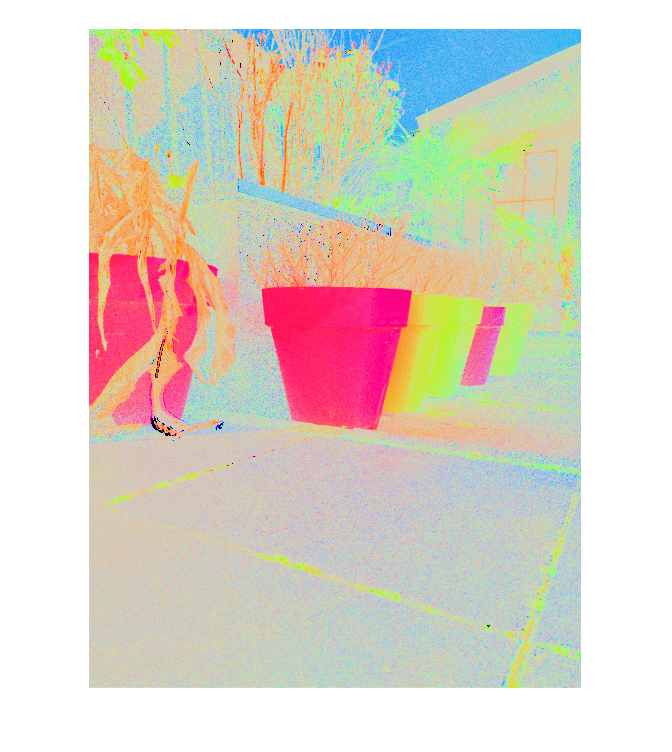

AlbedoLightMap = max(0.001, euclidianlength(Diffuse, 3));
Albedo = Diffuse ./ AlbedoLightMap;

imshow(lin2rgb(gather(Albedo)));

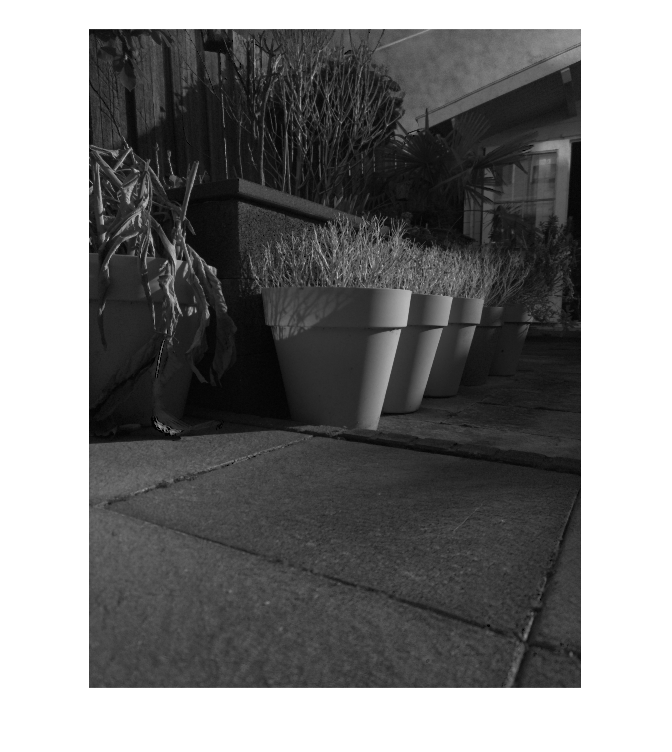

imshow(lin2rgb(gather(AlbedoLightMap)));

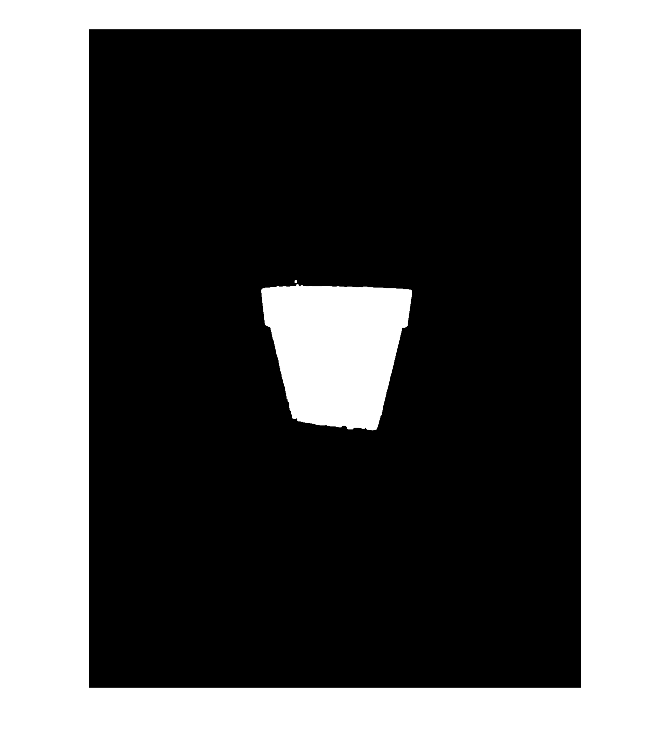


CompareVec = zeros([1 1 3]);
CompareVec(1, 1, :) = Albedo(1000, 700, :);
BinaryMap = euclidianlength(Albedo - CompareVec, 3) < 0.13;
BinaryMap = imclose(BinaryMap, strel('disk', 3));
BinaryMap = imopen(BinaryMap, strel('disk', 3));
BinaryMap = imdilate(BinaryMap, strel('disk', 1));

BinaryMap = imgaussfilt(BinaryMap .* 1.0, 0.5);
BinaryMap2 = zeros(size(BinaryMap));
BinaryMap2(500:1500, 500:1000, :) = BinaryMap(500:1500, 500:1000, :);
BinaryMap = BinaryMap2;
clear BinaryMap2;

imshow(lin2rgb(gather(BinaryMap)));

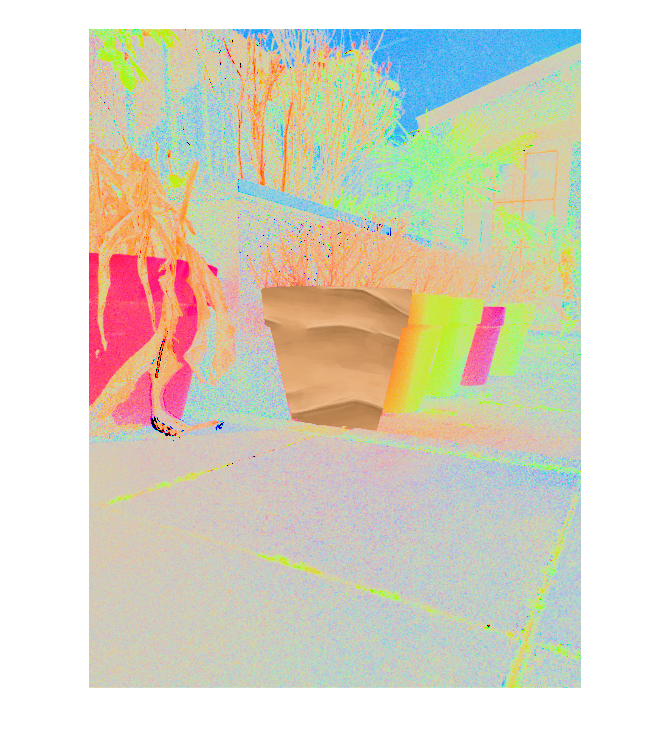


%Motif = gpuArray(rgb2lin(double(imread('web/motif.png')) / 255.0));
Motif = gpuArray(rgb2lin(double(imread('web/sand.png')) / 255.0));
%MotifAlbedoLightMap = euclidianlength(Motif, 3);
%MotifAlbedo = Motif ./ MotifAlbedoLightMap;
%clear Motif;
% clear MotifAlbedoLightMap;
%MotifAlbedo = repmat(MotifAlbedo, 6, 6, 1);
MotifAlbedo = repmat(Motif, 2, 2, 1);

[Y, X, ~] = size(Albedo);
ChangeToVec = MotifAlbedo(1:Y, 1:X, :);

Albedo = BinaryMap .* ChangeToVec + (1 - BinaryMap) .* Albedo;
imshow(lin2rgb(gather(Albedo)));

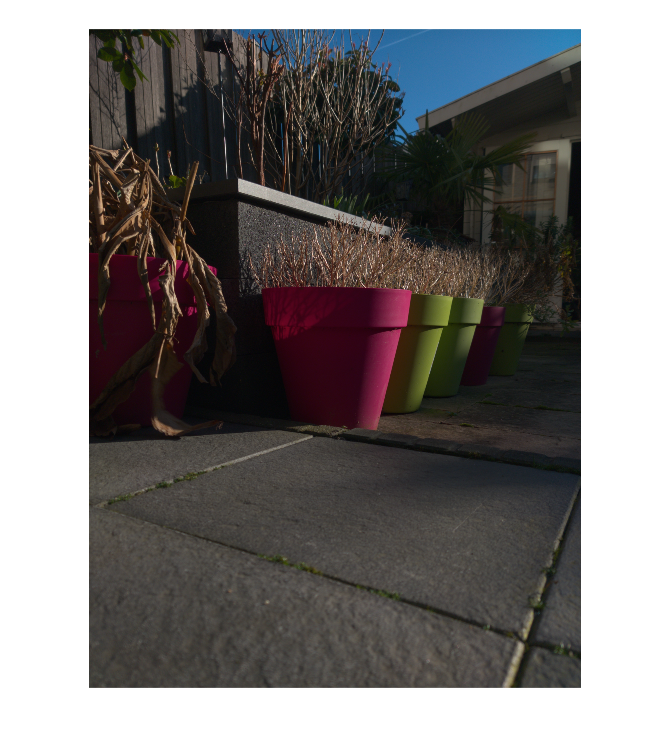


imshow(lin2rgb(gather(Diffuse + Specular)));

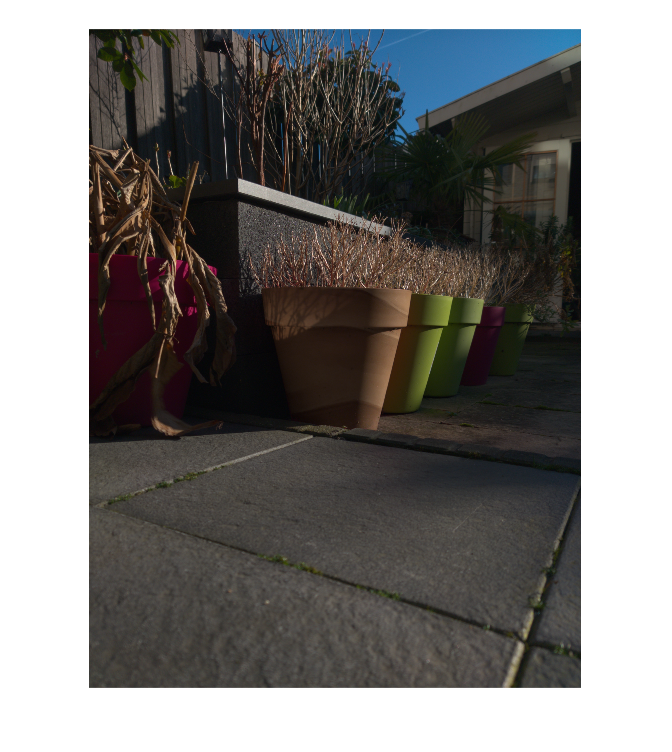

imshow(lin2rgb(gather(Albedo .* AlbedoLightMap + Specular)));


%imshow(lin2rgb(gather(DiffuseLightMap)));
%imshow(lin2rgb(gather(AlbedoLightMap)));
%imshow(lin2rgb(gather(AlbedoLightMapFac)));

AlbedoLAB = gpulin2lab(Albedo);
AlbedoLAB(:, :, 2) = -AlbedoLAB(:, :, 2);
Albedo2 = gpulab2lin(AlbedoLAB);

%imshow(lin2rgb(gather(Albedo .* AlbedoLightMapFac)));
%imshow(lin2rgb(gather(Albedo2 .* AlbedoLightMapFac)));

imshow(lin2rgb(gather(Albedo .* AlbedoLightMapFac + Specular)));
imshow(lin2rgb(gather(Albedo2 .* AlbedoLightMapFac + Specular)));

%imshow(lin2rgb(gather(AlbedoLightMap)));

%AlbedoLAB = gpuArray(rgb2lab(gather(Albedo), 'ColorSpace', 'linear-rgb'));
%AlbedoLAB(:, :, 2:3) = 1 - AlbedoLAB(:, :, 2:3);
%Albedo2 = gpuArray(lab2rgb(gather(AlbedoLAB), 'ColorSpace', 'linear-rgb'));
%Diffuse2 = Albedo2 .* AlbedoLightMap;

%imshow(lin2rgb(gather(Diffuse + Specular)));
%imshow(lin2rgb(gather(Diffuse2 + Specular)));

TonemappedDiffuse = tonemapimage(Diffuse, 0.4, 1.0);
%TonemappedDiffuse = TonemappedDiffuse ./ max(TonemappedDiffuse, [], [1 2 3]);
imshow(lin2rgb(gather(TonemappedDiffuse)));

TonemappedSpecular = tonemapimage(Specular, 0.7, 1.0);
%TonemappedSpecular = TonemappedSpecular ./ max(TonemappedSpecular, [], [1 2 3]);
imshow(lin2rgb(gather(TonemappedSpecular)));

TonemappedTotal = TonemappedDiffuse + TonemappedSpecular;
%TonemappedTotal = TonemappedTotal ./ max(TonemappedTotal, [], [1 2 3]);
imshow(lin2rgb(gather(TonemappedTotal)));

TonemappedMean = tonemapimage(MeanRGB, 0.4, 1.0);
%TonemappedMean = TonemappedMean ./ max(TonemappedMean, [], [1 2 3]);
imshow(lin2rgb(gather(TonemappedMean)));

imwrite(uint8(255.0 .* lin2rgb(gather(TonemappedDiffuse))), strcat('algo/', file, 't2d.tif'));
imwrite(uint8(255.0 .* lin2rgb(gather(TonemappedSpecular))), strcat('algo/', file, 't2s.tif'));

imwrite(uint8(255.0 .* lin2rgb(gather(TonemappedMean))), strcat('algo/', file, 't1.tif'));
imwrite(uint8(255.0 .* lin2rgb(gather(TonemappedTotal))), strcat('algo/', file, 't2.tif'));

%%%%%%%%%%%%%%%%%%

tonemappedSpecular = tonemapimage(Specular, 0.75, 1.0);
tonemappedSpecular = tonemappedSpecular / max(tonemappedSpecular, [], [1 2 3]);
imshow(lin2rgb(gather(tonemappedSpecular)));

MeanRGBMult = MeanRGB;
MeanRGBMult = MeanRGBMult ./ max(MeanRGBMult, [], [1 2 3]);
imwrite(uint8(255.0 .* lin2rgb(gather(MeanRGBMult))), strcat('algo/', file, 'rgb1.tif'));

MeanRGBMult = tonemapimage(MeanRGBMult, 0.5, 1.0);
MeanRGBMult = MeanRGBMult ./ max(MeanRGBMult, [], [1 2 3]);
imwrite(uint8(255.0 .* lin2rgb(gather(MeanRGBMult))), strcat('algo/', file, 'rgb2.tif'));

MeanRGBMult = MeanRGB .* sqrt(euclidianlength(tonemappedSpecular, 3));
MeanRGBMult = MeanRGBMult ./ max(MeanRGBMult, [], [1 2 3]);
imwrite(uint8(255.0 .* lin2rgb(gather(MeanRGBMult))), strcat('algo/', file, 'rgbmult1.tif'));

MeanRGBMult = tonemapimage(MeanRGBMult, 0.5, 1.0);
MeanRGBMult = MeanRGBMult ./ max(MeanRGBMult, [], [1 2 3]);
imwrite(uint8(255.0 .* lin2rgb(gather(MeanRGBMult))), strcat('algo/', file, 'rgbmult2.tif'));

tonemappedSpecularHSV = rgb2hsv(gpulin2rgb(tonemappedSpecular));

MeanRGBMult = tonemapimage(MeanRGB, 0.5, 1.0);
tonemappedMeanHSV = rgb2hsv(MeanRGBMult);
tonemappedMeanHSV(:, :, 3) = 0.5 .* tonemappedMeanHSV(:, :, 3) + 0.5 .* tonemappedSpecularHSV(:, :, 3);

MeanRGBMult = gpurgb2lin(hsv2rgb(tonemappedMeanHSV));
imwrite(uint8(255.0 .* lin2rgb(gather(MeanRGBMult))), strcat('algo/', file, 'hsv.tif'));

%tonemappedSpecular = tonemapimage(Specular, 0.9, 1.0);
%imshow(lin2rgb(gather(Specular)));
%imshow(lin2rgb(gather(tonemappedSpecular)));

%tonemappedDiffuseHSV = rgb2hsv(gpulin2rgb(max(0.0, Diffuse)));
%tonemappedDiffuseHSV(:, :, 3) = sigmoid(addDiff .* tonemappedDiffuseHSV(:, :, 3), sigmoidCut);

%tonemappedSpecularHSV = rgb2hsv(gpulin2rgb(Specular));
%tonemappedSpecularHSV(:, :, 3) = sigmoid(addSpec .* tonemappedSpecularHSV(:, :, 3), sigmoidCut);

%imshow(hsv2rgb(tonemappedDiffuseHSV));
%imshow(hsv2rgb(tonemappedSpecularHSV));
%imshow(hsv2rgb(tonemappedDiffuseHSV) + hsv2rgb(tonemappedSpecularHSV));

%clear sigmoidCut;
%clear addDiff;
%clear addSpec;

%tonemappedDiffuse = gpurgb2lin(hsv2rgb(tonemappedDiffuseHSV));

tonemappedMean = tonemapimage(MeanRGB, 0.7, 1.25);
tonemappedDiffuse = tonemapimage(max(0.0, Diffuse), 0.7, 1.25);
%imshow(gpulin2rgb(tonemappedDiffuse));

tonemappedDiffuseHSV = rgb2hsv(gpulin2rgb(max(0.0, Diffuse)));
tonemappedSpecularHSV = rgb2hsv(gpulin2rgb(Specular));
tonemappedSpecularHSV(:, :, 1:2) = tonemappedDiffuseHSV(:, :, 1:2);

tonemappedFinal = min(1.0, Diffuse + 1.5 .* gpurgb2lin(hsv2rgb(tonemappedSpecularHSV)));
tonemappedFinal = tonemapimage(tonemappedFinal, 0.7, 1.25);
imshow(gpulin2rgb(tonemappedFinal));

% imshow(lin2rgb(gather(tonemappedMean)));

imwrite(uint8(255.0 .* lin2rgb(gather(Diffuse))), strcat('algo/', file, 'rawdiffuse.tif'));
imwrite(uint8(255.0 .* lin2rgb(gather(Specular))), strcat('algo/', file, 'rawspecular.tif'));

imwrite(uint8(255.0 .* lin2rgb(gather(MeanRGB))), strcat('algo/', file, 'mapped0.tif'));
imwrite(uint8(255.0 .* lin2rgb(gather(tonemappedMean))), strcat('algo/', file, 'mapped1.tif'));
imwrite(uint8(255.0 .* lin2rgb(gather(tonemappedDiffuse))), strcat('algo/', file, 'mapped2.tif'));
imwrite(uint8(255.0 .* lin2rgb(gather(tonemappedFinal))), strcat('algo/', file, 'mapped3.tif'));

%imshow(lin2rgb(gather(tonemappedDiffuse + tonemappedSpecular)));